clc;clear;close all;

## 生成点

warning off

azimuth = 5.135899059569828;
elevation = 1.57897350050879;

r = 1;
x0 = r.*cos(azimuth).*cos(elevation);
y0 = r.*cos(azimuth).*sin(elevation);
z0 = r.*sin(azimuth);
Tao = [x0,y0,z0]

Tao =    -0.0034    0.4109   -0.9117


P3 = [0.698625642652000,1.04004032326448,-0.573794783259771]+Tao;
P4 = [0.710558671267955,-0.419236813348415,-0.777745273229581]-Tao;


num = 8;
laynum = 5;

% 测试 生成 一个截面 测点
Point_out = generate_unit_circle_with_normal_vector2(azimuth,elevation,num,laynum,P3,P4,0.6);


## 拟合圆柱

% 测试 测点的拟合
[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Point_out,P3,P4);

## A、B面点测试

testP = Point_out(:,20);
numShengLu = 4;
phi = pi/4;

toff = 0.05;
roff = 0.05;

[PointTable_A,PointTable_B] = Calculat_A_and_B_Points(MTaon',Mcenter',Mradial,Bottom_round_center1',Bottom_round_center2',testP,numShengLu,phi);
[PointTable_A_off,PointTable_B_off] = Calculat_A_and_B_Points_after_Offest(MTaon',Mcenter',Mradial,Bottom_round_center1',Bottom_round_center2',testP,numShengLu,phi,toff,roff);

## 绘图验证

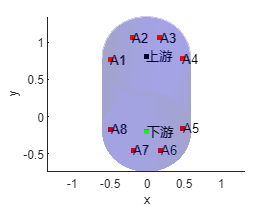

figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

% 绘制散点
% scatter3(Point_out(1,:),Point_out(2,:),Point_out(3,:),5,"filled");
% scatter3([P3(1),P4(1)],[P3(2),P4(2)],[P3(3),P4(3)],10,"filled");


% quiver3(0,0,0,A(1),A(2),A(3))
% quiver3(0,0,0,B(1),B(2),B(3))
% quiver3(0,0,0,C(1),C(2),C(3))
% quiver3(0,0,0,D(1),D(2),D(3))



% scatter3(xN1,yN1,zN1,20,'filled')
% scatter3(testP(1),testP(2),testP(3),20,'filled')
% plot3([xN1,testP(1)],[yN1,testP(2)],[zN1,testP(3)])


% scatter3(Tao2(1),Tao2(2),Tao2(3),20,'filled')
% plot3([xN1,Tao2(1)],[yN1,Tao2(2)],[zN1,Tao2(3)])
PointTable_A = PointTable_A';
PointTable_B = PointTable_B';


PointTable_A_off = PointTable_A_off';
PointTable_B_off = PointTable_B_off';

% scatter3(PointTable_A(:,1),PointTable_A(:,2),PointTable_A(:,3),20,'filled','red')
% scatter3(PointTable_B(:,1),PointTable_B(:,2),PointTable_B(:,3),20,'filled','blue')
% 
% scatter3(PointTable_A_off(:,1),PointTable_A_off(:,2),PointTable_A_off(:,3),20,'filled','yellow')
% scatter3(PointTable_B_off(:,1),PointTable_B_off(:,2),PointTable_B_off(:,3),20,'filled','yellow')


scatter3(PointTable_A(1,1),PointTable_A(1,2),PointTable_A(1,3),20,'filled','red')
text(PointTable_A(1,1),PointTable_A(1,2),PointTable_A(1,3),'A1')


scatter3(PointTable_A(2,1),PointTable_A(2,2),PointTable_A(2,3),20,'filled','red')
text(PointTable_A(2,1),PointTable_A(2,2),PointTable_A(2,3),'A2')

scatter3(PointTable_A(3,1),PointTable_A(3,2),PointTable_A(3,3),20,'filled','red')
text(PointTable_A(3,1),PointTable_A(3,2),PointTable_A(3,3),'A3')

scatter3(PointTable_A(4,1),PointTable_A(4,2),PointTable_A(4,3),20,'filled','red')
text(PointTable_A(4,1),PointTable_A(4,2),PointTable_A(4,3),'A4')

scatter3(PointTable_A(5,1),PointTable_A(5,2),PointTable_A(5,3),20,'filled','red')
text(PointTable_A(5,1),PointTable_A(5,2),PointTable_A(5,3),'A5')

scatter3(PointTable_A(6,1),PointTable_A(6,2),PointTable_A(6,3),20,'filled','red')
text(PointTable_A(6,1),PointTable_A(6,2),PointTable_A(6,3),'A6')

scatter3(PointTable_A(7,1),PointTable_A(7,2),PointTable_A(7,3),20,'filled','red')
text(PointTable_A(7,1),PointTable_A(7,2),PointTable_A(7,3),'A7')

scatter3(PointTable_A(8,1),PointTable_A(8,2),PointTable_A(8,3),20,'filled','red')
text(PointTable_A(8,1),PointTable_A(8,2),PointTable_A(8,3),'A8')



scatter3(Bottom_round_center1(1),Bottom_round_center1(2),Bottom_round_center1(3),20,'filled','black')
text(Bottom_round_center1(1),Bottom_round_center1(2),Bottom_round_center1(3),'上游')


scatter3(Bottom_round_center2(1),Bottom_round_center2(2),Bottom_round_center2(3),20,'filled','green')
text(Bottom_round_center2(1),Bottom_round_center2(2),Bottom_round_center2(3),'下游')

## 判断左右



Psy1 = Bottom_round_center1;
Pxy2 = Bottom_round_center2;
Pup3 = Bottom_round_center1 + [1, 0, 0];
Pup4 = Bottom_round_center2 + [1, 0, 0];
DirZX = Psy1 - Pxy2; % 向上游

% 计算方向
PA1 = PointTable_A(2,:);  % 右侧
[aaa,bbb,ccc] = foot_of_perpendicular_from_a_point_to_a_line(PA1,Psy1,Pxy2);
FPA1 = [aaa,bbb,ccc];
FPA1Up = FPA1 + [1, 0, 0];
DirA1 = FPA1 - PA1;  % 指向垂足
Dirup = [1,0,0];

% 计算夹角
DirPD1 = cross(DirA1,Dirup);
thetaA1 = rad2deg(acos(dot(DirZX, DirPD1) / (norm(DirZX) * norm(DirPD1))))     % 夹角（弧度）

thetaA1 = 179.7790


% 判断左右
if thetaA1 > 90
    rightflag = 0;
else
    rightflag = 1;
end


## 排序


scatter3(Pup3(1),Pup3(2),Pup3(3),20,"filled",'yellow')


% 组织点的坐标到矩阵中
vertices = [Psy1; Pxy2; Pup3; Pup4];

% 绘制平面

patch('Vertices', vertices, 'Faces', [1 2 4 3], ...
      'FaceColor', 'cyan', 'FaceAlpha', 0.5); % 半透明平面

% 计算平面方程

Dirtemp1 = cross(DirZX,Dirup); %A1-4一侧，右侧向量
PMdian3 = Pxy2 + Dirtemp1;

Dirn = cross(Dirtemp1,DirZX);
Dirn = Dirn./norm(Dirn)  % 平面法向量

Dirn =     1.0000    0.0015   -0.0033


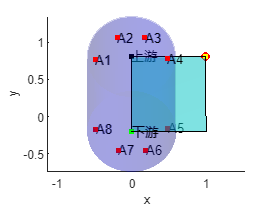


Ptest = Psy1 + Dirn;
scatter3(Ptest(1),Ptest(2),Ptest(3),40,"filled",'red')



A = Dirn(1);
B = Dirn(2);
C = Dirn(3);

% 计算 D
D = -(A * Psy1(1) + B * Psy1(2) + C * Psy1(3));




% 计算点到平面的距离
numerator = A * PA1(1) + B * PA1(2) + C * PA1(3) + D; % 平面方程左侧的值
denominator = sqrt(A^2 + B^2 + C^2); % 法向量的模长
distance = numerator / denominator; % 距离公式


## 测试

SoundPoint1 =  [PointTable_A(1,1),PointTable_A(1,2),PointTable_A(1,3)];
SoundPoint2 =  [PointTable_A(8,1),PointTable_A(8,2),PointTable_A(8,3)];

[SoundAngle,SoundLength] = RepeatSurvey(SoundPoint1,SoundPoint2,Bottom_round_center1,Bottom_round_center2)

SoundAngle = 0.7854

SoundLength = 0.9975

SoundAngle = SoundAngle/pi*180

SoundAngle = 45